# 5. State Estimation and Sensor Fusion

Overview: use sensor measurements to get state vector

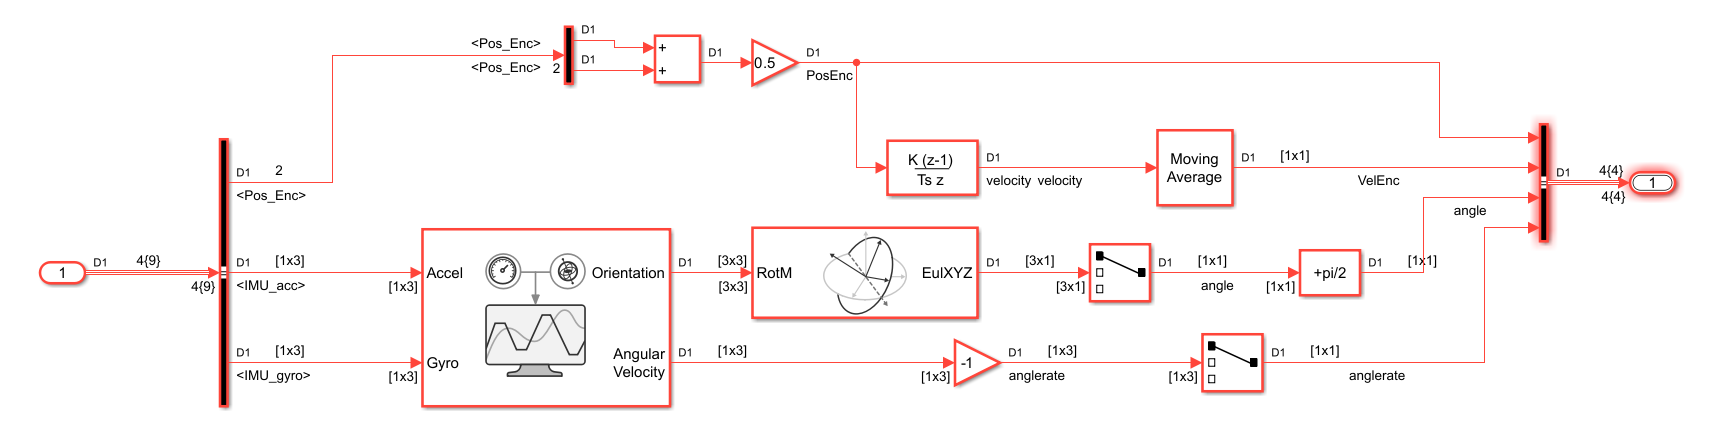

Separate use of individual sensor from the IMU unit are not suitable to derive states such as the balancing angle. However, the combination of e.g. a gyroscope and accelerometers can overcome this limitation, which is also the reason why they are often integrated on a single chip. The approach to reconstruct state information from multiple sensor readings is called Sensor Fusion and can be implemented with different algorithms. For our example we make use of the IMU Filter block from the Navigation Toolbox:

[https://www.mathworks.com/help/nav/ref/imufilter.html](https://www.mathworks.com/help/nav/ref/imufilter.html)

open_system("P4_RaspberryModel_with_DT/DistributedController/SignalProc_StateControl/SensorFusion/SensorFusion")

Some of the parameters for the IMU Filter Block can be determined from the sensor measurements. (load them)

- Accelerometer noise (FilterBlock)

- Gyroscope noise (FilterBlock)

## Noise of the sensor readings (Noise needed for Sensorfusion)

The noise can typically be expressed as the expected square deviation from the mean. This calculation can be done for every axes. For the sake of simplicity we use an average value for the IMU Filter block.

load('SensorReadingsForAnalysis.mat')
acc_rec.data=logsout{5}.Values.Data*9.81; %acc
acc_rec.time=logsout{5}.Values.Time;

gyro_rec.data=logsout{6}.Values.Data; %gyro
gyro_rec.time=logsout{6}.Values.Time;

#### Accelerometer Noise [(m/s^2)^2]:

mean(var(acc_rec.data))

ans = 4.4378e-04

#### Gyroscope Noise [(rad/s)^2]:

mean(var(gyro_rec.data))

ans = 1.5569e-05

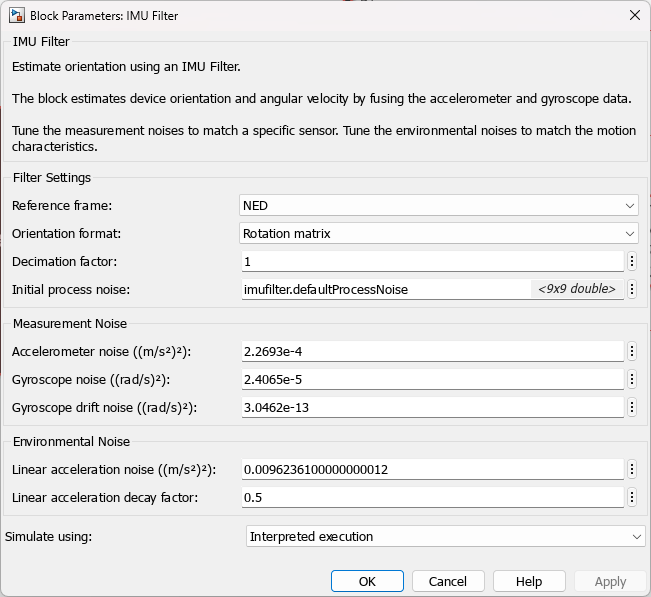

For the purpose of this tutorial we did not alter the values of the Environmental Noise. Gyrodrift Noise was also not investigated....

Now that we have the sensor modeling in place we can compare the simulated and estimated state vectors for validation.

open_system("Ex7_Validation_StateEstimation")

How well do the simulated and estimated states fit. Can we use the estimated states for the control as well. Try to switch the input and make a simulation.

What could be the reason for this behavior?